clc; clear; close all;

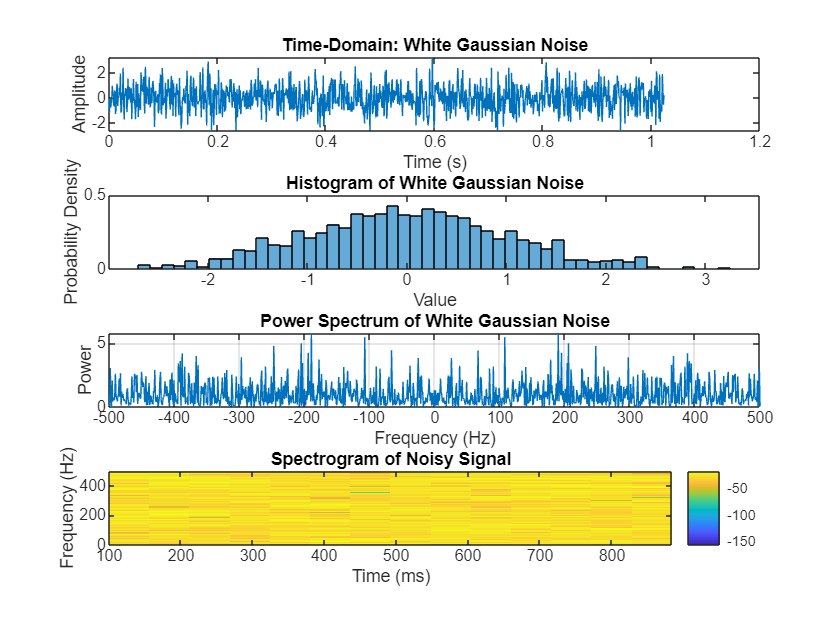

%% Generate Gaussian White Noise
N = 1024; % Number of samples
fs = 1000; % Sampling frequency (Hz)
t = (0:N-1)/fs; % Time axis
x = randn(N,1); % White Gaussian noise

%% Plot Statistics of Original Noise
figure;
subplot(4,1,1);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: White Gaussian Noise');

subplot(4,1,2);
histogram(x, 50, 'Normalization', 'pdf');
xlabel('Value');
ylabel('Probability Density');
title('Histogram of White Gaussian Noise');

subplot(4,1,3);
X = fft(x);
f = linspace(-fs/2, fs/2, N);
plot(f, abs(fftshift(X)).^2 / N);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum of White Gaussian Noise');
grid on;

subplot(4,1,4);
% Spectrogram for Noisy Signal
spectrogram(x, 256, 200, 256, fs, 'yaxis');
title('Spectrogram of Noisy Signal');
colorbar;

% Design a low-pass filter
fc = 100; % Cutoff frequency in Hz
[b, a] = butter(4, fc/(fs/2), 'low'); % 4th-order Butterworth low-pass filter
x_filtered = filter(b, a, x); % Apply the filter

% Compute and plot power spectral density
X_filtered = fft(x_filtered);
X_filtered_magnitude = abs(fftshift(X_filtered)).^2 / N;

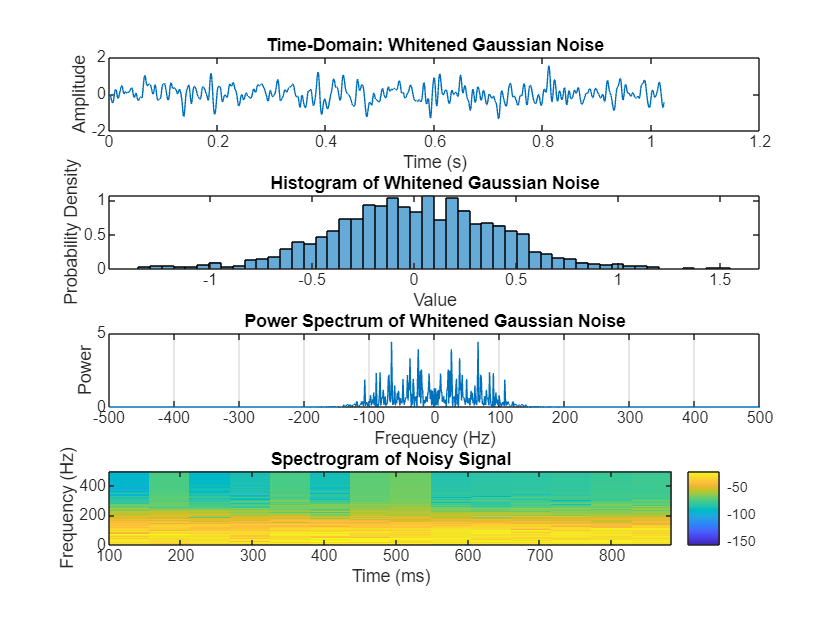

%% Plot Statistics of Whitened Signal
figure;
subplot(4,1,1);
plot(t, x_filtered);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Whitened Gaussian Noise');

subplot(4,1,2);
histogram(x_filtered, 50, 'Normalization', 'pdf');
xlabel('Value');
ylabel('Probability Density');
title('Histogram of Whitened Gaussian Noise');

% Plot the power spectrum of the whitened signal
subplot(4,1,3);
X_filter_freq = fft(x_filtered);
plot(f, abs(fftshift(X_filter_freq)).^2 / N);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum of Whitened Gaussian Noise');
grid on;

subplot(4,1,4);
% Spectrogram for Noisy Signal
spectrogram(x_filtered, 256, 200, 256, fs, 'yaxis');
title('Spectrogram of Noisy Signal');
colorbar;